% 请实现本章介绍的JPEG解码，
% 输入是你生成的jpegcodes.mat文件。
% 分别用客观(PSNR)和主观方式评价编解码效果如何。
clear;
load jpegcodes.mat;
load JpegCoeff.mat;

% 解DC系数
% 利用DC，得到Category
[~,DC_size] = size(DC);
DC_Category = [];
c_error = [];
i = 1;
while i <= DC_size
    if isequal(DC(i:i+1),[0,0]) % 00-0
        cur_cat = 0;
        i = i + 2;
    elseif isequal(DC(i:i+2),[0,1,0])
        cur_cat = 1;
        i = i + 3;
    elseif isequal(DC(i:i+2),[0,1,1])
        cur_cat = 2;
        i = i + 3;
    elseif isequal(DC(i:i+2),[1,0,0])
        cur_cat = 3;
        i = i + 3;
    elseif isequal(DC(i:i+2),[1,0,1])
        cur_cat = 4;
        i = i + 3;
    elseif isequal(DC(i:i+2),[1,1,0])
        cur_cat = 5;
        i = i + 3;
    elseif isequal(DC(i:i+3),[1,1,1,0])
        cur_cat = 6;
        i = i + 4;
    elseif isequal(DC(i:i+4),[1,1,1,1,0])
        cur_cat = 7;
        i = i + 5;
    elseif isequal(DC(i:i+5),[1,1,1,1,1,0])
        cur_cat = 8;
        i = i + 6;
    elseif isequal(DC(i:i+6),[1,1,1,1,1,1,0])
        cur_cat = 9;
        i = i + 7;
    elseif isequal(DC(i:i+7),[1,1,1,1,1,1,1,0])
        cur_cat = 10;
        i = i + 8;
    else
        cur_cat = 11;
        i = i + 9;
    end

    Mag = DC(i:i+cur_cat-1);
    if cur_cat == 0
        c_error = [c_error,0];
    elseif Mag(1) == 1 % 正数
        c_error = [c_error,bin2dec(num2str(Mag))];
    else % 负数
        c_error = [c_error,-bin2dec(num2str(1-Mag))];
    end
    i = i + cur_cat;
end

% 得到误差后还原
[~,size_DC] = size(c_error);
c_DC = zeros(1,size_DC);
c_DC(1) = c_error(1);
for i = 2:1:size_DC
    c_DC(i) = c_DC(i-1)-c_error(i);
end

% 解AC系数
c_AC_All = zeros(63,315);
c_AC = [];
[~,AC_size] = size(AC);
i = 1;
count = 1;
while i <= AC_size-16
    if isequal(AC(i:i+3),[1,0,1,0])
        code_length = 4;
        Run = 0;
        Size = 0;
    elseif isequal(AC(i:i+10),[ones(1,8),0,0,1])
        code_length = 11;
        Run = 15;
        Size = 0;
    else
        for j = 1:1:160
            code_length = ACTAB(j,3);
            if isequal(AC(i:i+code_length-1),ACTAB(j,4:3+code_length))
                Run = ACTAB(j,1);
                Size = ACTAB(j,2);
                break;
            end
        end
    end

    % 先写入Run个0
    c_AC = [c_AC,zeros(1,Run)];
    if Run == 15 && Size == 0 % ZRL再写一个0
        c_AC = [c_AC,0];
    end
    i = i + code_length;

    % 再写入Amplitude
    if Size > 0
        Amp = AC(i:i+Size-1);
        if Amp(1) > 0 % 正数
            c_AC = [c_AC,bin2dec(num2str(Amp))];
        else % 负数
            c_AC = [c_AC,-bin2dec(num2str(1-Amp))];
        end
    end
    i = i + Size;

    % EOB
    if Run == 0 && Size == 0
        [~,cur_AC_size] = size(c_AC);
        c_AC_All(1:cur_AC_size,count) = c_AC';
        count = count + 1;
        c_AC = [];
    end
end

small_size = AC_size-i+1;
% 此时不可能出现ZRL
while small_size > 4
    for j = 1:1:160
        code_length = ACTAB(j,3);
        if code_length > small_size - 4
            continue;
        end
        if isequal(AC(i:i+code_length-1),ACTAB(j,4:3+code_length))
            Run = ACTAB(j,1);
            Size = ACTAB(j,2);
            break;
        end
    end
    % 先写入Run个0
    c_AC = [c_AC,zeros(1,Run)];
    if Run == 15 && Size == 0 % ZRL再写一个0
        c_AC = [c_AC,0];
    end
    i = i + code_length;

    % 再写入Amplitude
    if Size > 0
        Amp = AC(i:i+Size-1);
        if Amp(1) > 0 % 正数
            c_AC = [c_AC,bin2dec(num2str(Amp))];
        else % 负数
            c_AC = [c_AC,-bin2dec(num2str(1-Amp))];
        end
    end
    i = i + Size;
    small_size = AC_size-i+1;
end

[~,cur_AC_size] = size(c_AC);
c_AC_All(1:cur_AC_size,count) = c_AC';

% 反量化&DCT逆变换
[~,num_block] = size(c_DC);
blocks = zeros(8,8,num_block);
for i = 1:1:num_block
    blocks(:,:,i)=antizigzag([c_DC(i),c_AC_All(:,i)']); % 量化值
    blocks(:,:,i)=blocks(:,:,i).*double(QTAB); 
    blocks(:,:,i)=idct2(blocks(:,:,i));
end

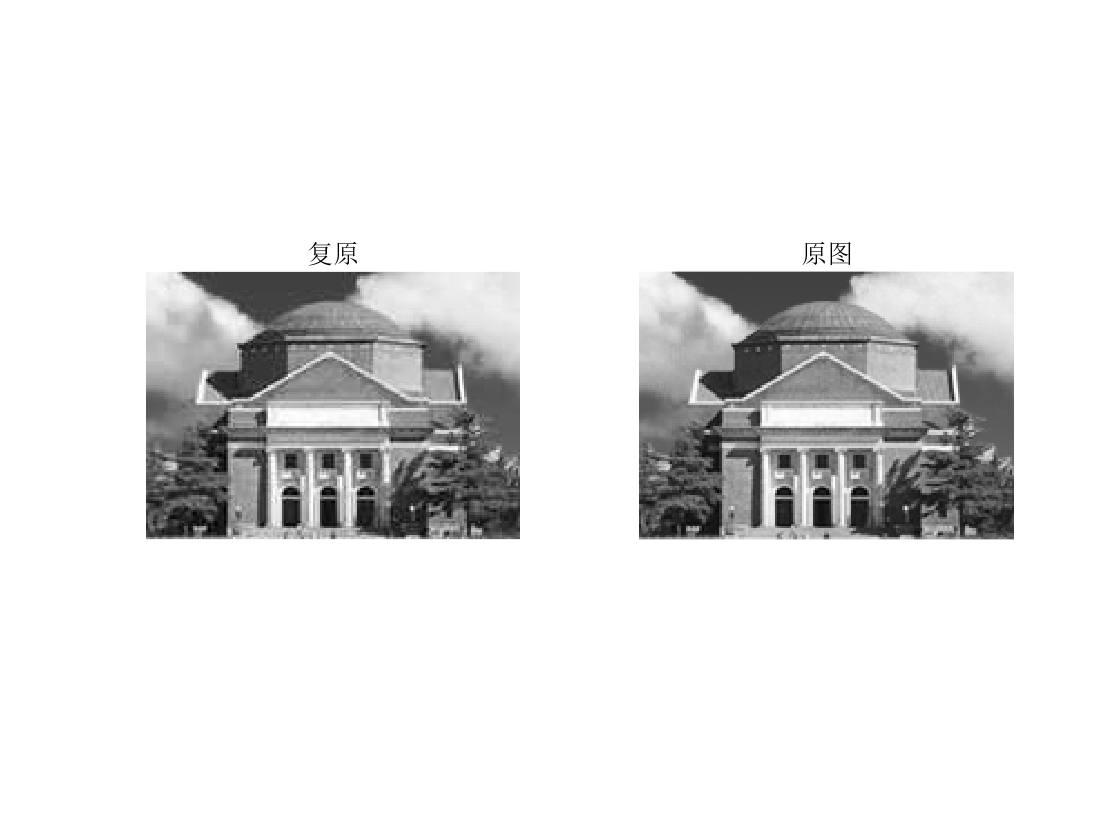

% 拼接
img = zeros(H,W);
for i = 1:1:H/8
    for j = 1:1:W/8
        img(8*i-7:8*i,8*j-7:8*j)=blocks(:,:,W*(i-1)/8+j);
    end
end
img = img + 128;
subplot(1,2,1)
imshow(uint8(img));
title('复原')
load hall.mat
subplot(1,2,2)
imshow(hall_gray);
title('原图')

% 计算PSNR
MSE = 0;
for i = 1:1:H
    for j = 1:1:W
        MSE = MSE + (double(img(i,j))-double(hall_gray(i,j))).^2;
    end
end
MSE = MSE/(H*W)

MSE = 49.5873


PSNR = 10*log10((255^2)/MSE)

PSNR = 31.1771